% % connectivity values come from import values in CONN, you can find them in
% % set up->second level covariates. for details see HOWTO_connectivity_and_behavior_correlations.docx 
% 
% addpath /Users/k.siudakrzywicka/Desktop/RDS_fMRI/RDS_localizers/scripts
% cd /Users/k.siudakrzywicka/Desktop/RDS_fMRI/Controls/color_rs_connectivity/behavioral_corelates

% naming_categ = readtable('color_categorization_naming_2ndBlock.xlsx');
% subs = [1 2 3 6 8:23 ];
%
% partial = naming_categ{:, [2,3]}
% 
% behavior = naming_categ{:,7 };


Gender = categorical(partial(:,1));
Age = partial(:,2);

IVs = rmmissing(table(Gender, Age, behavior));
IVs.Age = zscore(IVs.Age);
IVs.RT = zscore(IVs.behavior);
IVs.behavior = [];
% connectivity values come from import values in CONN, you can find them in
% set up->second level covariates. for details see HOWTO_connectivity_and_behavior_correlations.docx 

PCC_aMTG = [-0.0437327 0.204121 0.214168 0.144569 0.0979717 0.143297 0.256646 -0.0461484 0.137161 -0.32824 -0.059902 0.16525 0.134405 0.0968771 -0.0139668 NaN -0.0364638 0.0962955 0.148974 NaN]';
PCC_pMTG = [-0.102643 0.126645 0.303922 0.118971 0.184869 0.124062 0.249373 -0.0807016 0.269338 -0.281279 -0.0281272 -0.000114652 0.0118272 0.107977 -0.0376007 NaN -0.0250033 0.214788 0.170565 NaN]';
PCC_RDS = [0.0746116 0.132856 0.213245 0.111323 0.231646 0.148588 0.230983 0.131317 0.225872 -0.375882 -0.0863032 0.0881594 0.188548 0.129274 -0.133069 NaN -0.0739008 0.0586843 0.136695 NaN]';

VWFA_pMTG = [-0.0193152 0.056352 -0.0193091 -0.00963124 0.311898 0.161472 -0.0617169 0.083871 -0.0279307 0.00186289 -0.115217 0.112901 0.270371 -0.0376636 -0.208305 NaN 0.08725 -0.233355 0.0924544 NaN]';
VWFA_aMTG = [0.00985526 0.109287 -0.0956005 0.164656 0.291632 -0.0173411 0.00994892 0.182427 0.0536675 0.0166333 -0.124239 0.0269214 0.0977342 -0.0545523 -0.186126 NaN 0.0899484 -0.356432 0.0897821 NaN]';
VWFA_RDS = [0.0572547 0.0390671 -0.149659 0.357112 0.226607 0.0140029 0.0702111 0.0644431 0.0833635 -0.00426579 0.0224392 -0.0555433 0.146186 0.0337127 -0.10593 -0.108746 0.0664275 -0.31745 0.122595 0.180728]';

LOC_pMTG =[0.222693 -0.222871 0.28609 -0.0108748 -0.154032 0.141359 -0.0569973 -0.268134 0.332662 -0.036685 0.144858 -0.168866 -0.0667978 0.0918449 0.0154657 NaN 0.145194 -0.0753916 0.123785 NaN]';
LOC_aMTG =[0.276091 -0.051028 0.309615 0.15001 -0.200638 0.0130408 0.0426314 -0.17799 0.13429 0.0791903 0.130548 0.12685 -0.0910538 0.11019 -0.0764819 NaN 0.0911551 0.102333 0.171609 NaN]';
LOC_RDS = [0.341058 -0.106525 0.198604 0.00349724 -0.0180607 0.136061 -0.0230805 -0.126365 0.286579 0.0122656 -0.0275099 -0.0633376 -0.0168457 0.34915 -0.154373 0.112779 -0.00418837 0.135008 0.173876 -0.259432]';

connectivity = rmmissing(table(PCC_aMTG, PCC_pMTG, PCC_RDS, VWFA_pMTG, VWFA_aMTG, VWFA_RDS, LOC_pMTG, LOC_aMTG, LOC_RDS));
connectivity{:,:} = zscore(table2array(connectivity));
model_names = strcat(connectivity.Properties.VariableNames, '_model');



%calculate all models
for i = 1: width(connectivity)
    regressions(i).name = model_names{i};
    
    regressions(i).model = fitlm([IVs, connectivity(:,i)],[connectivity.Properties.VariableNames{i} ' ~ Gender+Age+RT']);
    
    regressions(i).partialR_RT = beta_to_partialR(regressions(i).model, 'RT');
    data_temp = regressions(i).model.Variables
    regressions(i).partialR_RT_2 = partialcorr(data_temp{:,3}, data_temp{:,4}, [double(data_temp{:,1}), data_temp{:,2}])
    
    regressions(i).simple_model = step(regressions(i).model,'NSteps',10);
end

r = -0.5668

data_temp = 18×4 table
    Gender       Age          RT        PCC_aMTG
    ______    _________    _________    ________

    0          0.072235    -0.099381    -0.83569
    0          -0.21671      0.19215     0.94099
    0         -0.072235     -0.71807       1.013
    0           0.79459      0.32923     0.51411
    0          -0.36118      0.37589     0.18009
    0            1.0835      0.27805     0.50499
    0             1.228     -0.18163      1.3175
    0         -0.072235      -0.3652    -0.85301
    0           0.36118     -0.33738     0.46101
    0           0.50565       2.2897     -2.8751
    0           0.50565       1.5321     -0.9516
    0             1.228       1.0632     0.66236
    0           0.65012       0.7291     0.44125
    0          0.072235     -0.84326     0.17224
    1          -0.79459       -2.057    -0.62232
    1  

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Adding Gender:RT, FStat = 4.7696, pValue = 0.047888


r = -0.5236

data_temp = 18×4 table
    Gender       Age          RT        PCC_pMTG
    ______    _________    _________    ________

    0          0.072235    -0.099381     -1.1569
    0          -0.21671      0.19215     0.34721
    0         -0.072235     -0.71807      1.5101
    0           0.79459      0.32923     0.29687
    0          -0.36118      0.37589     0.72914
    0            1.0835      0.27805     0.33026
    0             1.228     -0.18163      1.1523
    0         -0.072235      -0.3652     -1.0129
    0           0.36118     -0.33738      1.2832
    0           0.50565       2.2897     -2.3287
    0           0.50565       1.5321    -0.66806
    0             1.228       1.0632     -0.4843
    0           0.65012       0.7291    -0.40597
    0          0.072235     -0.84326     0.22475
    1          -0.79459       -2.057     -0.7302
    1  

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Removing Age, FStat = 0.015703, pValue = 0.90206
2. Removing Gender, FStat = 1.6767, pValue = 0.21494


r = -0.6559

data_temp = 18×4 table
    Gender       Age          RT        PCC_RDS 
    ______    _________    _________    ________

    0          0.072235    -0.099381    -0.03174
    0          -0.21671      0.19215     0.33949
    0         -0.072235     -0.71807     0.85186
    0           0.79459      0.32923     0.20225
    0          -0.36118      0.37589     0.96914
    0            1.0835      0.27805     0.43976
    0             1.228     -0.18163     0.96492
    0         -0.072235      -0.3652     0.32968
    0           0.36118     -0.33738     0.93234
    0           0.50565       2.2897      -2.903
    0           0.50565       1.5321     -1.0574
    0             1.228       1.0632    0.054609
    0           0.65012       0.7291     0.69445
    0          0.072235     -0.84326     0.31666
    1          -0.79459       -2.057     -1.3554
    1  

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Adding Gender:RT, FStat = 9.7742, pValue = 0.0080287
2. Removing Age, FStat = 2.3026, pValue = 0.15309


r = 0.2110

data_temp = 18×4 table
    Gender       Age          RT        VWFA_pMTG
    ______    _________    _________    _________

    0          0.072235    -0.099381    -0.31064 
    0          -0.21671      0.19215     0.22245 
    0         -0.072235     -0.71807     -0.3106 
    0           0.79459      0.32923    -0.24242 
    0          -0.36118      0.37589      2.0229 
    0            1.0835      0.27805     0.96306 
    0             1.228     -0.18163    -0.60938 
    0         -0.072235      -0.3652     0.41633 
    0           0.36118     -0.33738    -0.37134 
    0           0.50565       2.2897    -0.16144 
    0           0.50565       1.5321     -0.9863 
    0             1.228       1.0632     0.62086 
    0           0.65012       0.7291      1.7303 
    0          0.072235     -0.84326    -0.43991 
    1          -0.79459       -2.057    

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Removing Age, FStat = 0.021569, pValue = 0.88533
2. Removing Gender, FStat = 0.56131, pValue = 0.46532
3. Removing RT, FStat = 2.2627, pValue = 0.15201


r = 0.0757

data_temp = 18×4 table
    Gender       Age          RT        VWFA_aMTG 
    ______    _________    _________    __________

    0          0.072235    -0.099381     -0.049164
    0          -0.21671      0.19215       0.62352
    0         -0.072235     -0.71807      -0.76261
    0           0.79459      0.32923       0.99811
    0          -0.36118      0.37589        1.8571
    0            1.0835      0.27805      -0.23316
    0             1.228     -0.18163      -0.04853
    0         -0.072235      -0.3652        1.1183
    0           0.36118     -0.33738       0.24724
    0           0.50565       2.2897    -0.0033085
    0           0.50565       1.5321      -0.95635
    0             1.228       1.0632      0.066294
    0           0.65012       0.7291       0.54536
    0          0.072235     -0.84326       -0.4849
    1          -0.79459 

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Adding Age:RT, FStat = 8.182, pValue = 0.013387
2. Removing Gender, FStat = 1.2678, pValue = 0.28054


r = 0.0453

data_temp = 18×4 table
    Gender       Age          RT        VWFA_RDS 
    ______    _________    _________    _________

    0          0.072235    -0.099381      0.13843
    0          -0.21671      0.19215     0.012548
    0         -0.072235     -0.71807      -1.2937
    0           0.79459      0.32923       2.2138
    0          -0.36118      0.37589       1.3106
    0            1.0835      0.27805     -0.16093
    0             1.228     -0.18163       0.2281
    0         -0.072235      -0.3652      0.18818
    0           0.36118     -0.33738      0.31913
    0           0.50565       2.2897     -0.28737
    0           0.50565       1.5321     -0.10254
    0             1.228       1.0632     -0.64227
    0           0.65012       0.7291      0.75394
    0          0.072235     -0.84326    -0.024511
    1          -0.79459       -2.057    

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Adding Age:RT, FStat = 8.8451, pValue = 0.010762


r = -0.2055

data_temp = 18×4 table
    Gender       Age          RT        LOC_pMTG 
    ______    _________    _________    _________

    0          0.072235    -0.099381       1.1482
    0          -0.21671      0.19215      -1.4347
    0         -0.072235     -0.71807       1.5157
    0           0.79459      0.32923      -0.2058
    0          -0.36118      0.37589      -1.0357
    0            1.0835      0.27805      0.67667
    0             1.228     -0.18163     -0.47317
    0         -0.072235      -0.3652      -1.6971
    0           0.36118     -0.33738       1.7856
    0           0.50565       2.2897     -0.35542
    0           0.50565       1.5321      0.69696
    0             1.228       1.0632      -1.1217
    0           0.65012       0.7291     -0.52998
    0          0.072235     -0.84326      0.38965
    1          -0.79459       -2.057    

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Removing Gender, FStat = 0.010201, pValue = 0.92098
2. Removing Age, FStat = 0.11724, pValue = 0.73679
3. Removing RT, FStat = 0.73647, pValue = 0.40347


r = -0.0024

data_temp = 18×4 table
    Gender       Age          RT        LOC_aMTG
    ______    _________    _________    ________

    0          0.072235    -0.099381       1.525
    0          -0.21671      0.19215    -0.81994
    0         -0.072235     -0.71807      1.7653
    0           0.79459      0.32923     0.62119
    0          -0.36118      0.37589     -1.8924
    0            1.0835      0.27805    -0.36066
    0             1.228     -0.18163    -0.14855
    0         -0.072235      -0.3652     -1.7301
    0           0.36118     -0.33738     0.50851
    0           0.50565       2.2897     0.11353
    0           0.50565       1.5321     0.48168
    0             1.228       1.0632     0.45517
    0           0.65012       0.7291     -1.1069
    0          0.072235     -0.84326     0.33575
    1          -0.79459       -2.057     -1.0024
    1  

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Removing RT, FStat = 7.7161e-05, pValue = 0.99312
2. Removing Age, FStat = 0.15353, pValue = 0.70069
3. Removing Gender, FStat = 0.019286, pValue = 0.89128


r = -0.2965

data_temp = 18×4 table
    Gender       Age          RT        LOC_RDS 
    ______    _________    _________    ________

    0          0.072235    -0.099381      1.7883
    0          -0.21671      0.19215     -1.0685
    0         -0.072235     -0.71807     0.87906
    0           0.79459      0.32923    -0.36625
    0          -0.36118      0.37589    -0.50384
    0            1.0835      0.27805     0.47986
    0             1.228     -0.18163    -0.53588
    0         -0.072235      -0.3652     -1.1951
    0           0.36118     -0.33738      1.4406
    0           0.50565       2.2897    -0.31028
    0           0.50565       1.5321    -0.56415
    0             1.228       1.0632    -0.79283
    0           0.65012       0.7291    -0.49609
    0          0.072235     -0.84326      1.8399
    1          -0.79459       -2.057     -1.3739
    1  

regressions = 1×9 struct array with fields:
    name
    model
    partialR_RT
    partialR_RT_2
    simple_model


1. Removing Age, FStat = 0.1727, pValue = 0.68402
2. Removing Gender, FStat = 0.98817, pValue = 0.33596
3. Removing RT, FStat = 0.65866, pValue = 0.42894


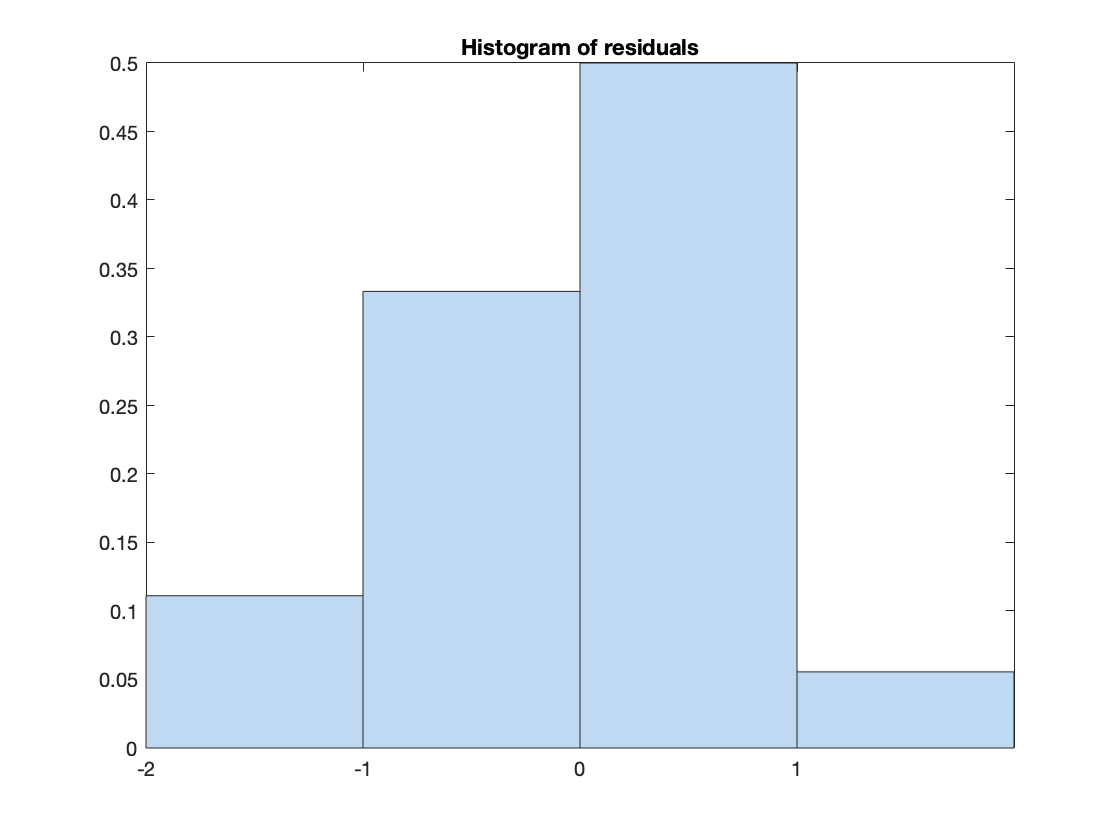

%figures and diagnostics for PCC - RDS connectivity

plotResiduals(regressions(3).model)

anova(regressions(3).model,  'summary')

ans = 3×5 table
                SumSq     DF    MeanSq       F       pValue 
                ______    __    _______    _____    ________

    Total           17    17          1                     
    Model       7.5676     3     2.5225    3.744    0.036427
    Residual    9.4324    14    0.67375                     


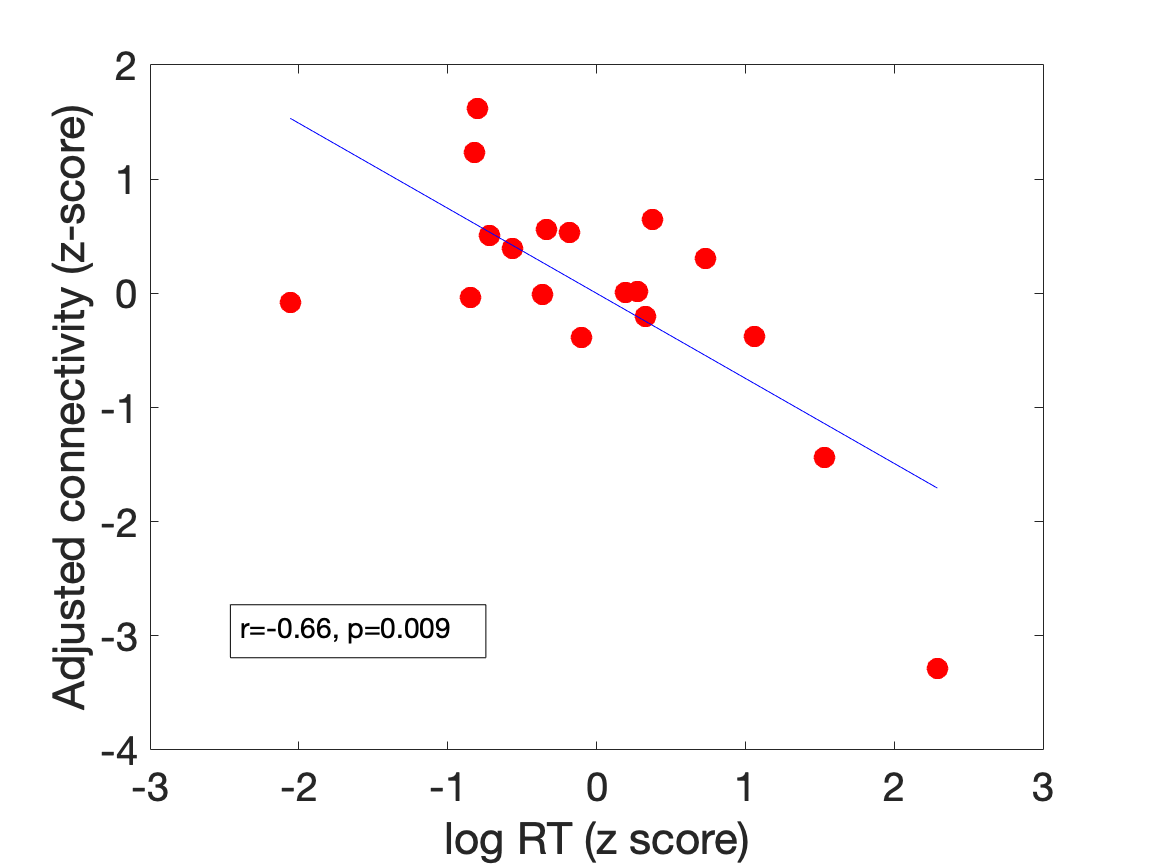

plotAdjustedResponse(regressions(3).model,'RT','markerfacecolor', 'r', 'MarkerEdgeColor', 'r', 'markersize', 10)
set(gca, 'FontSize', 20)
xlabel('log RT (z score)')
ylabel('Adjusted connectivity (z-score)')
title(' ')
s=findobj('type','legend');
delete(s)
a = annotation('textbox', [0.2 0 0.3 0.3], 'String', ...
    ['r=' num2str(round(regressions(3).partialR_RT,2))...
    ', p=' num2str(round(regressions(3).model.Coefficients.pValue(4),3))],...
    'FitBoxToText','on');
a.FontSize = 14;
set(gcf,'Units','inches','Position',[0 0 8 6])
plot2pdf('PC-RDS-c.naming.pdf')

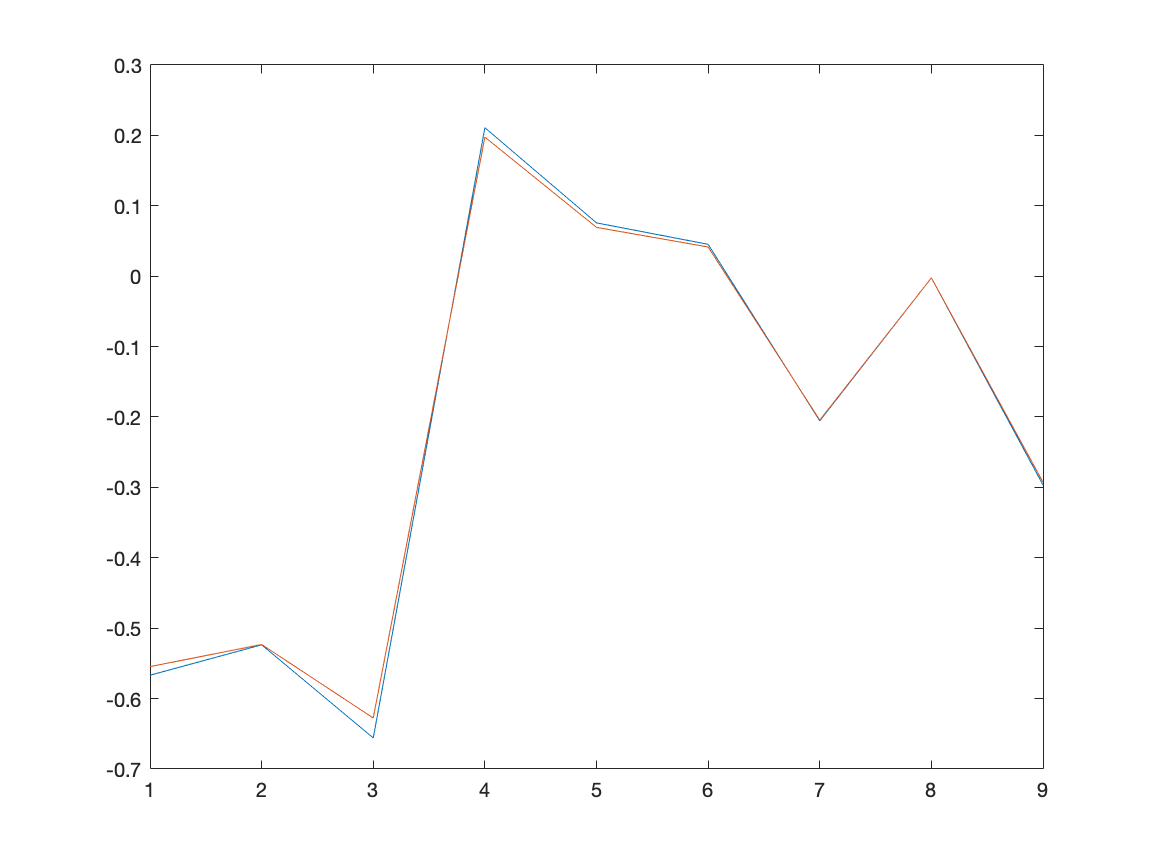

%double-check partial corrs
plot([regressions(:).partialR_RT])
hold on
plot([regressions(:).partialR_RT_2])
hold off

%Run summary statistics for each of the models

for i = 1:9
    regressions(i).name
    anova(regressions(i).model,  'summary')
end

ans = 'PCC_aMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq       F       pValue 
                ______    __    _______    ______    _______

    Total           17    17          1                     
    Model       5.7297     3     1.9099    2.3725    0.11421
    Residual     11.27    14    0.80502                     


ans = 'PCC_pMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq       F       pValue 
                ______    __    _______    ______    _______

    Total           17    17          1                     
    Model        4.675     3     1.5583    1.7701    0.19895
    Residual    12.325    14    0.88035                     


ans = 'PCC_RDS_model'

ans = 3×5 table
                SumSq     DF    MeanSq       F       pValue 
                ______    __    _______    _____    ________

    Total           17    17          1                     
    Model       7.5676     3     2.5225    3.744    0.036427
    Residual    9.4324    14    0.67375                     


ans = 'VWFA_pMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq        F       pValue 
                ______    __    _______    _______    _______

    Total           17    17          1                      
    Model       2.6656     3    0.88852    0.86779    0.48087
    Residual    14.334    14     1.0239                      


ans = 'VWFA_aMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq        F       pValue 
                ______    __    _______    _______    _______

    Total           17    17          1                      
    Model       2.8271     3    0.94237    0.93087    0.45168
    Residual    14.173    14     1.0123                      


ans = 'VWFA_RDS_model'

ans = 3×5 table
                SumSq     DF    MeanSq        F       pValue
                ______    __    _______    _______    ______

    Total           17    17          1                     
    Model       2.7498     3    0.91661    0.90052    0.4655
    Residual     14.25    14     1.0179                     


ans = 'LOC_pMTG_model'

ans = 3×5 table
                 SumSq     DF    MeanSq        F       pValue 
                _______    __    _______    _______    _______

    Total            17    17          1                      
    Model       0.88585     3    0.29528    0.25654    0.85542
    Residual     16.114    14      1.151                      


ans = 'LOC_aMTG_model'

ans = 3×5 table
                 SumSq     DF     MeanSq        F        pValue 
                _______    __    ________    ________    _______

    Total            17    17           1                       
    Model       0.19259     3    0.064198    0.053475    0.98303
    Residual     16.807    14      1.2005                       


ans = 'LOC_RDS_model'

ans = 3×5 table
                SumSq     DF    MeanSq        F       pValue 
                ______    __    _______    _______    _______

    Total           17    17          1                      
    Model        1.868     3    0.62266    0.57608    0.64015
    Residual    15.132    14     1.0809                      



for i = 1:9
    regressions(i).name
    anova(regressions(i).simple_model,  'summary')
end

ans = 'PCC_aMTG_model'

ans = 5×5 table
                   SumSq     DF    MeanSq       F        pValue 
                   ______    __    _______    ______    ________

    Total              17    17          1                      
    Model          8.7548     4     2.1887    3.4509    0.039411
    . Linear       5.7297     3     1.9099    3.0113    0.068674
    . Nonlinear    3.0251     1     3.0251    4.7696    0.047888
    Residual       8.2452    13    0.63425                      


ans = 'PCC_pMTG_model'

ans = 3×5 table
                SumSq     DF    MeanSq       F      pValue 
                ______    __    _______    _____    _______

    Total           17    17          1                    
    Model        3.282     1      3.282    3.828    0.06809
    Residual    13.718    16    0.85737                    


ans = 'PCC_RDS_model'

ans = 5×5 table
                   SumSq     DF    MeanSq       F        pValue  
                   ______    __    _______    ______    _________

    Total              17    17          1                       
    Model          10.662     3      3.554    7.8506    0.0025809
    . Linear       7.5392     2     3.7696    8.3268     0.004145
    . Nonlinear    3.1228     1     3.1228    6.8981     0.019925
    Residual       6.3379    14    0.45271                       


ans = 'VWFA_pMTG_model'

ans = 3×5 table
                  SumSq       DF    MeanSq     F     pValue
                __________    __    ______    ___    ______

    Total               17    17      1                    
    Model       4.3664e-32     0    Inf       Inf    NaN   
    Residual            17    17      1                    


ans = 'VWFA_aMTG_model'

ans = 5×5 table
                   SumSq     DF    MeanSq       F        pValue 
                   ______    __    _______    ______    ________

    Total              17    17          1                      
    Model          7.4534     3     2.4845    3.6435    0.039396
    . Linear       1.8732     2    0.93659    1.3735     0.28532
    . Nonlinear    5.5803     1     5.5803    8.1834    0.012582
    Residual       9.5466    14     0.6819                      


ans = 'VWFA_RDS_model'

ans = 5×5 table
                   SumSq     DF    MeanSq       F        pValue 
                   ______    __    _______    ______    ________

    Total              17    17          1                      
    Model          8.5198     4     2.1299    3.2651    0.046334
    . Linear       2.7498     3    0.91661    1.4051     0.28576
    . Nonlinear    5.7699     1     5.7699    8.8451    0.010762
    Residual       8.4802    13    0.65233                      


ans = 'LOC_pMTG_model'

ans = 3×5 table
                  SumSq       DF    MeanSq     F     pValue
                __________    __    ______    ___    ______

    Total               17    17      1                    
    Model       1.1631e-32     0    Inf       Inf    NaN   
    Residual            17    17      1                    


ans = 'LOC_aMTG_model'

ans = 3×5 table
                  SumSq       DF    MeanSq     F     pValue
                __________    __    ______    ___    ______

    Total               17    17      1                    
    Model       3.2108e-32     0    Inf       Inf    NaN   
    Residual            17    17      1                    


ans = 'LOC_RDS_model'

ans = 3×5 table
                  SumSq       DF    MeanSq     F     pValue
                __________    __    ______    ___    ______

    Total               17    17      1                    
    Model       8.4592e-33     0    Inf       Inf    NaN   
    Residual            17    17      1                    


Analysis on behavior

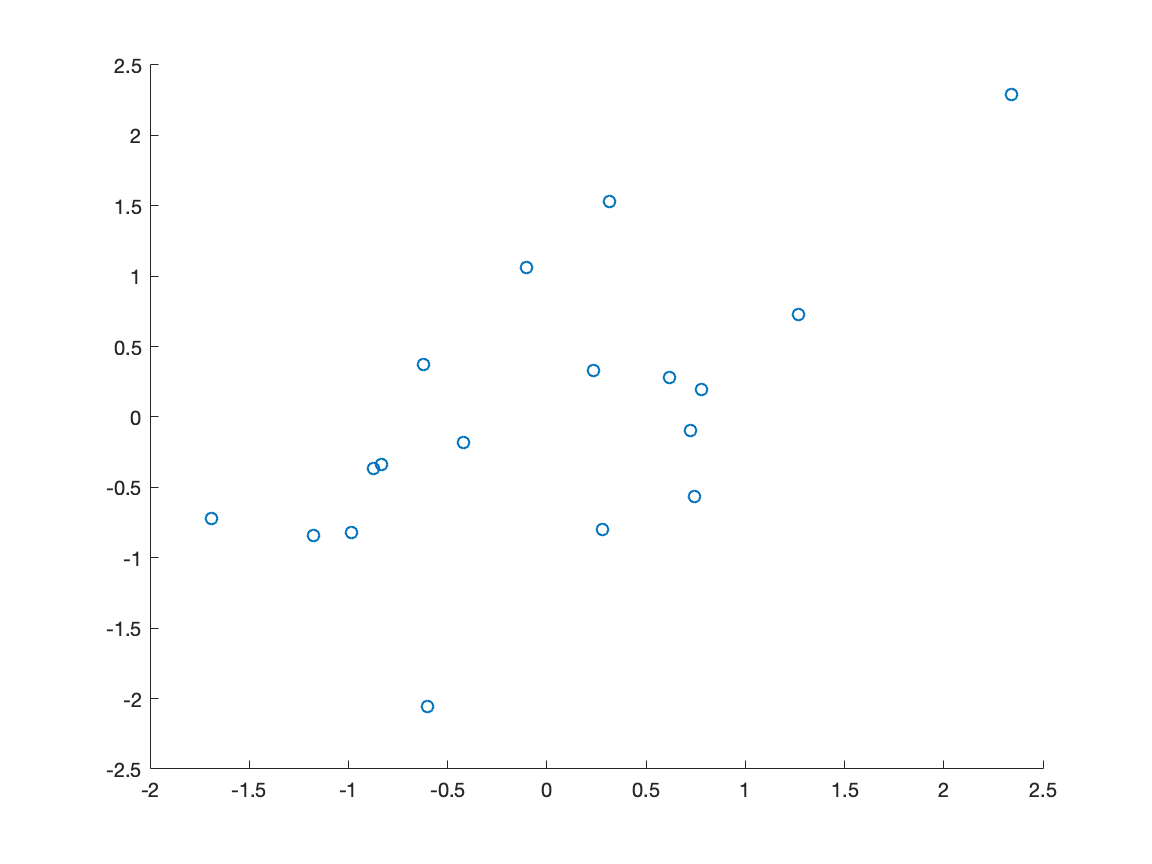

Beha_data = table(IVs.Gender, IVs.Age, zscore(rmmissing(naming_categ.Naming_log_meanRT)), zscore(rmmissing(naming_categ.Categ_log_meanRT)));

Beha_data.Properties.VariableNames = {'Gender', 'Age' ,'RT_naming', 'RT_categ'};
scatter(Beha_data.RT_categ, Beha_data.RT_naming)

beha_model = fitlm(Beha_data,'RT_naming ~ Gender+Age+RT_categ')

beha_model = Linear regression model:
    RT_naming ~ 1 + Gender + Age + RT_categ

Estimated Coefficients:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)      0.29692    0.18741      1.5844       0.13543
    Gender_1         -1.3362     0.5595     -2.3881       0.03158
    Age            -0.044672     0.2429    -0.18391       0.85672
    RT_categ         0.61341    0.14791      4.1472    0.00098699


Number of observations: 18, Error degrees of freedom: 14
Root Mean Squared Error: 0.595
R-squared: 0.709,  Adjusted R-Squared 0.646
F-statistic vs. constant model: 11.3, p-value = 0.000485

beta_to_partialR(beha_model, 'RT_categ')

r = 0.9213

ans = 0.9213

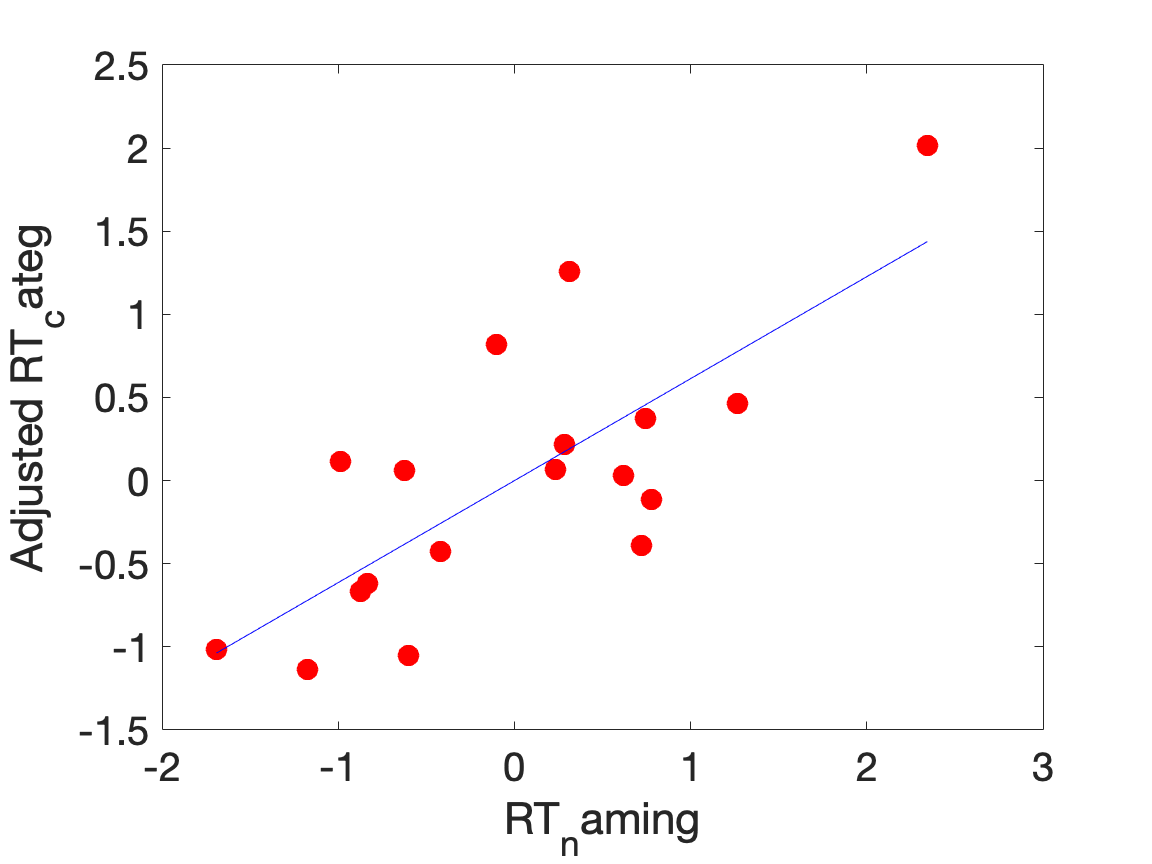

plotAdjustedResponse(beha_model,'RT_categ','markerfacecolor', 'r', 'MarkerEdgeColor', 'r', 'markersize', 10)
set(gca, 'FontSize', 20)
xlabel('RT_naming')
ylabel('Adjusted RT_categ')
title(' ')
s=findobj('type','legend');
delete(s)
% a = annotation('textbox', [0.2 0 0.3 0.3], 'String', ...
%     ['r=' num2str(round(regressions(3).partialR_RT,2))...
%     ', p=' num2str(round(regressions(3).model.Coefficients.pValue(4),3))],...
%     'FitBoxToText','on');
% a.FontSize = 14;
set(gcf,'Units','inches','Position',[0 0 8 6])
plot2pdf('PC-RDS-c.naming.pdf')

partialcorr(Beha_data.RT_categ, Beha_data.RT_naming, [double(Beha_data{:, 1}), Beha_data{:, 2}])

ans = 0.7425

UnivarScatter([Beha_data.RT_categ, Beha_data.RT_naming])

ans =     1.2111    2.1653
    1.0704    2.0000
    1.0000    2.0704
    0.8347    2.1653
    0.9296    2.0000
    0.7889    1.8347
    1.0000    1.8347
    0.7889    2.1653
    1.2111    2.0000
    1.0000    2.0000


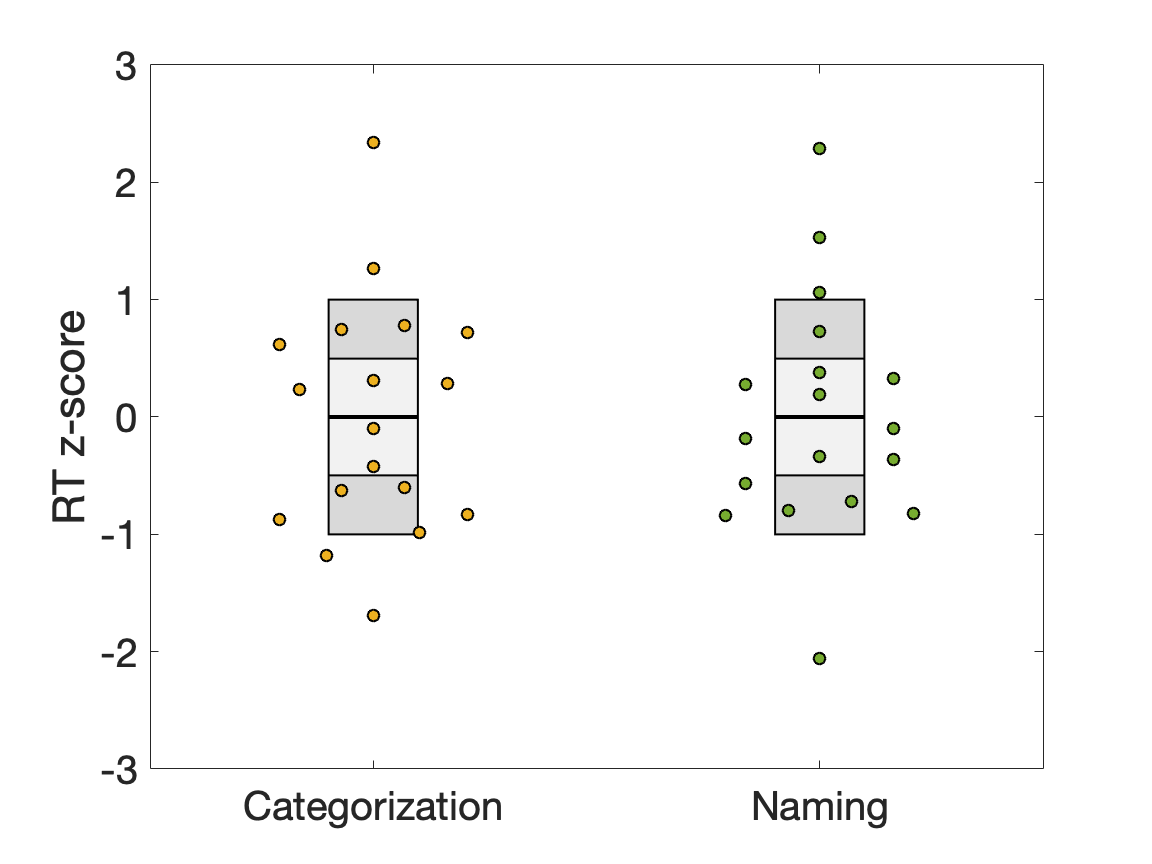

set(gca, 'FontSize', 20)
ylabel('RT z-score')
xticklabels({'Categorization', 'Naming'})